# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 01-Oct-2020 17:41:23

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Index", "Girthin", "Heightft", "Volumeft3"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
trees = readtable("/MATLAB Drive/trees.csv", opts)

trees = 32×4 table
    Index    Girthin    Heightft    Volumeft3
    _____    _______    ________    _________

      1        8.3         70         10.3   
      2        8.6         65         10.3   
      3        8.8         63         10.2   
      4       10.5         72         16.4   
      5       10.7         81         18.8   
      6       10.8         83         19.7   
      7         11         66         15.6   
      8         11         75         18.2   
      9       11.1         80         22.6   
     10       11.2         75         19.9   
     11       11.3         79         24.2   
     12       11.4         76           21   
     13       11.4         76         21.4   
     14       11.7         69         21.3   
     15         12         75         19.1   
     16       12.9         74         22.2   


## Clear temporary variables

clear opts

## Generate a scatterplot

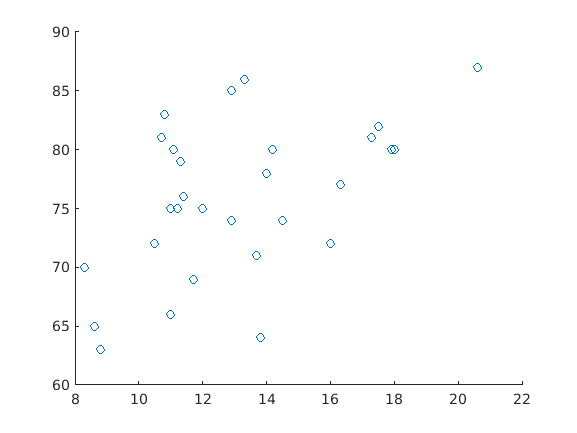

scatter(trees.Girthin,trees.Heightft)

## Compute correlation between girth and height

[https://www.mathworks.com/help/stats/corr.html](https://www.mathworks.com/help/stats/corr.html)

The following command will return NaN ("not a number") because there are rows with no values in the table.

corr(trees.Girthin,trees.Heightft)

ans = NaN

The collowing command will compute the correlation between girth and height after ignoring empty values

corr(trees.Girthin,trees.Heightft,"rows","complete")

ans = 0.5193

We can see that correlation is 0.5. This is not a very high correlation but is better than zero.

## Compute a correlation matrix

[https://www.mathworks.com/help/matlab/data_analysis/linear-correlation.html](https://www.mathworks.com/help/matlab/data_analysis/linear-correlation.html)

The following command computes a correlation matrix. This is a matrix that shows the pairwise correlation between columns 2 (girth), 3 (height), and 4 (volume).

corrcoef(trees{:,2:4},"rows","complete")

ans =     1.0000    0.5193    0.9671
    0.5193    1.0000    0.5982
    0.9671    0.5982    1.0000


In the above code, the segment `trees{:,2:4}` produces a matrix with all the rows of the table, and only columns 2 to 4. We use this notation because `corrcoef` needs a matrix (not a table). If you are not sure of this notation, read this: [https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html)

We can observe that there is a high correlation between columns 3 and 4. That is, there is a high correlation between the height and the volume of the trees. We can show this more clearly if we produce a heatmap using the following code:

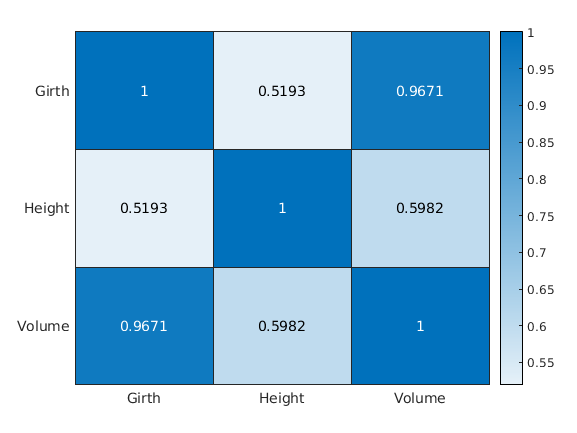

corr_matrix = corrcoef(trees{:,2:4},"rows","complete");
xvalues = {'Girth', 'Height', 'Volume'};
yvalues = {'Girth', 'Height', 'Volume'};
heatmap(xvalues, yvalues, corr_matrix)